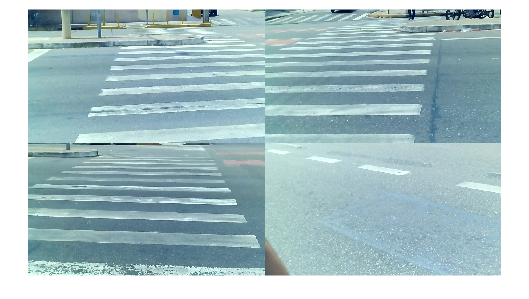

imlist = cell(1);

imlist{1} = imread("c1_passage_pieton\c1_p1_2.jpg");
imlist{2} = imread("c2_passage_pieton\c2_p1_1.jpg");
imlist{3} = imread("c3_passage_pieton\c3_p1_1.jpg");
imlist{4} = imread("c4_passage_pieton\c4_p1_5.jpg"); 
montage(imlist)

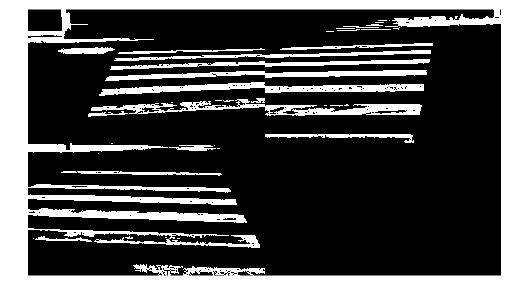


imlistgray = cell(1);
kernel = ones(3, 3) / 9;
for i = 1:4
    imlistgray{i} = imresize(imlist{i},[720,1280]);

    if size(imlistgray{i}, 3) == 3
        imlistgray{i} = rgb2gray(imlistgray{i});
    else
        imlistgray{i} = imlistgray{i};
    end
    % threshold = graythresh(imlistgray{i});
    imlistgray{i} = imbinarize(imlistgray{i}, 'adaptive');
    % imlistgray{i} = imfilter(imlistgray{i},kernel);
    imlistgray{i} = bwareaopen(imlistgray{i},8000);
end
montage(imlistgray)

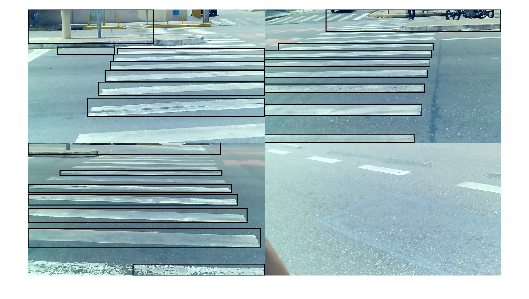


imlistbox = imlist;
for i = 1:4
    stats = regionprops(imlistgray{i});
    for j = 1:numel(stats)
        imlistbox{i} = insertShape(imlistbox{i}, 'rectangle', stats(j).BoundingBox, 'Color', 'black', 'LineWidth', 5);
    end

end
montage(imlistbox)

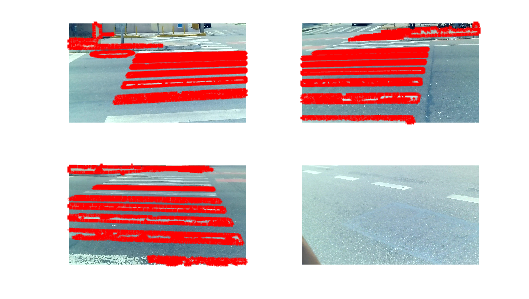

Error using bwboundaries
Expected input number 1, BW, to be two-dimensional.

Error in bwboundaries>parseInputs (line 202)
validateattributes(BW_in, {'numeric','logical'}, {'real','2d','nonsparse'}, ...

Error in bwboundaries (line 149)
[BW, conn, findHoles] = p


for i = 1:4
    B = bwboundaries(imlistgray{i});
    subplot(2,2,i);
    imshow(imlist{i});
    hold on;
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2)
    end
    hold off;
end